%Load the dataset
data = load("visiblehuman.mat");
dataHead = data.head;
dataFresh = data.head_fresh;
dataFrozen = data.head_frozen;
dataMRI = data.head_mri;

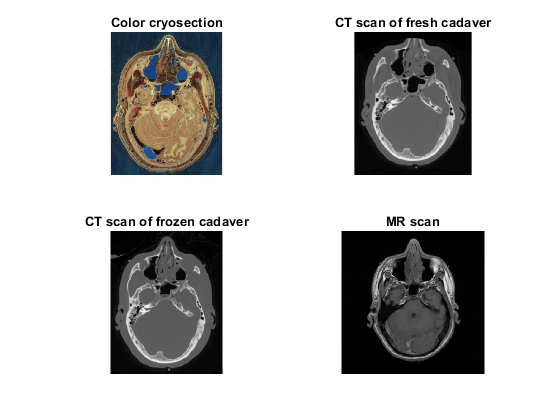

%Visualize the data
figure();
subplot(2, 2, 1);
imshow(dataHead), title("Color cryosection");
subplot(2, 2, 2);
imshow(dataFresh), title("CT scan of fresh cadaver");
subplot(2, 2, 3);
imshow(dataFrozen), title("CT scan of frozen cadaver");
subplot(2, 2, 4);
imshow(dataMRI), title("MR scan");

%Load the annotated points, save them in their respective matrices and
%calculate the mean landmarks
data1 = load("SelPointsG.mat");
data2 = load("SelPointsM.mat");
data3 = load("SelPointsZ.mat");

%Load landmarks for Color Cryosection
ColCryo = zeros([10 2 3]);
ColCryo(:, :, 1) = data1.ColCryoPoints;
ColCryo(:, :, 2) = data2.ColCryoPoints;
ColCryo(:, :, 3) = data3.ColCryoPoints;
ColCryoMean = mean(ColCryo, 3);

%Load landmarks of fresh cadaver CT scan
CTFresh = zeros([10 2 3]);
CTFresh(:, :, 1) = data1.CTFreshPoints;
CTFresh(:, :, 2) = data2.CTFreshPoints;
CTFresh(:, :, 3) = data3.CTFreshPoints;
CTFreshMean = mean(CTFresh, 3);

%Load landmarks of frozen cadaver CT scan
CTFrozen = zeros([10 2 3]);
CTFrozen(:, :, 1) = data1.CTFrozenPoints;
CTFrozen(:, :, 2) = data2.CTFrozenPoints;
CTFrozen(:, :, 3) = data3.CTFrozenPoints;
CTFrozenMean = mean(CTFrozen, 3);

%Load landmarks for MR scan
MRI = zeros([10 2 3]);
MRI(:, :, 1) = data1.MRPoints;
MRI(:, :, 2) = data2.MRPoints;
MRI(:, :, 3) = data3.MRPoints;
MRIMean = mean(MRI, 3);

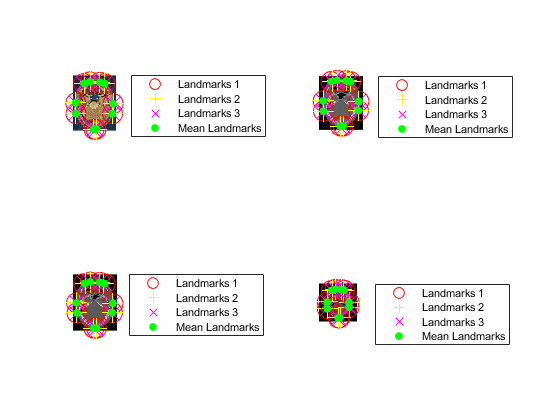

%Visualize the landmarks
figure();
subplot(2, 2, 1);
ShowLandmarks(dataHead, ColCryo);
subplot(2, 2, 2);
ShowLandmarks(dataFresh, CTFresh);
subplot(2, 2, 3);
ShowLandmarks(dataFrozen, CTFrozen);
subplot(2, 2, 4);
ShowLandmarks(dataMRI, MRI);


%Calculate the Fiducial localization error (FLE)
disp("FLE matrix and its variance");

FLE matrix and its variance


[f, sig] = FiducialLocalizationError(ColCryo)

f =    11.9176   -0.9032
   -0.9032    1.9567


sig = 6.9372

%Obtain parameters which would register the MR image to the frozen CT image using
%a similarity transform (scaling, rotation and translation)
disp("Optimal parameters to transform MRI to frozen CT scan");

Optimal parameters to transform MRI to frozen CT scan


[s1, R1, t1] = SimilarityTransform(MRIMean, CTFrozenMean)

s1 = 1.9382

R1 =     0.9998   -0.0217
    0.0217    0.9998


t1 =   -72.6588
  -21.1903


FLE = FiducialRegistrationError(MRIMean, CTFrozenMean)

FLE = 5.0259


disp("Optimal parameter to transform frozen CT scan to MRI");

Optimal parameter to transform frozen CT scan to MRI


[s2, R2, t2] = SimilarityTransform(CTFrozenMean, MRIMean)

s2 = 0.5148

R2 =     0.9998    0.0217
   -0.0217    0.9998


t2 =    37.9242
   10.3653


FLE = FiducialRegistrationError(CTFrozenMean, MRIMean)

FLE = 1.3349


R1 * R2

ans =     1.0000   -0.0000
    0.0000    1.0000


s1 * s2

ans = 0.9978

s2 * R2 * t1

ans =   -37.6334
  -10.0930


t2

t2 =    37.9242
   10.3653


%Transform the MRI image using the obtained parameters s1, R1 and t1
x = 1:size(dataFrozen, 2);
y = 1:size(dataFrozen, 1);
CTMesh = meshgrid(x, y)

CTMesh =      1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30    31    32    33    34    35    36    37    38    39    40    41    42    43    44    45    46    47    48    49    50
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30    31    32    33    34    35    36    37    38    39    40    41    42    43    44    45    46    47    48    49    50
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30    31    32    33    34    35    36    37    38    39    40    41    42    43    44    45    46    47    48    49    50
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    

size(dataMRI)

ans =    256   256


size(dataFrozen)

ans =    451   353


MRIMesh = 1:1:256;
CTMeshX = 1:1:size(dataFrozen, 1);
CTMeshY = 1:1:size(dataFrozen, 2);
F = zeros(size(dataFrozen));
midx = ceil((size(dataFrozen,1)+1)/2);
midy = ceil((size(dataFrozen,2)+1)/2);
for i = 1:size(dataMRI,1)
    for j = 1:size(dataMRI,2)
        x=s1*((i-midx)*R1(1,1)+(j-midy)*R1(2,1)) +t1(1);
        y=s1*((i-midx)*R1(1,2)+(j-midy)*R1(2,2)) +t1(2);
        x = round(x)+497;
        y = round(y)+285;
        if x>=1 && y>=1 && x<=size(dataFrozen,1) && y<=size(dataFrozen,2)
            F(x, y) = dataMRI(i, j);
        end
    end
end

% [row, col, v] = find(F)
% x=s1*(((1:size(dataMRI, 1))-midx)*R1(1,1)+((1:size(dataMRI, 2))-midy)*R1(2,1)) +t1(1)
% [x, y] = meshgrid(1:max(row), 1:max(col))
% [Xq, Yq] = meshgrid(1:size(F, 1), 1:size(F, 2))
% F2 = interp2(x, y, v, Xq, Yq)

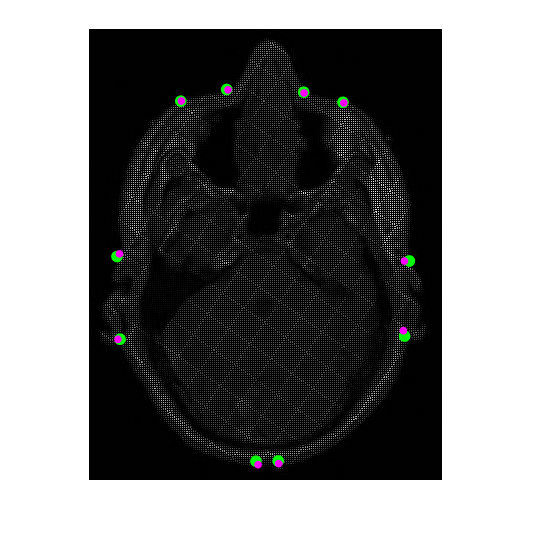

%Visualize the images with the landmarks
figure();
imshow(F, [])
hold on;
plot(CTFrozenMean(:, 1), CTFrozenMean(:, 2), 'g.', "MarkerSize", 30);
plot(MRITransform(:, 1), MRITransform(:, 2), 'm.', "MarkerSize", 20);
hold off;

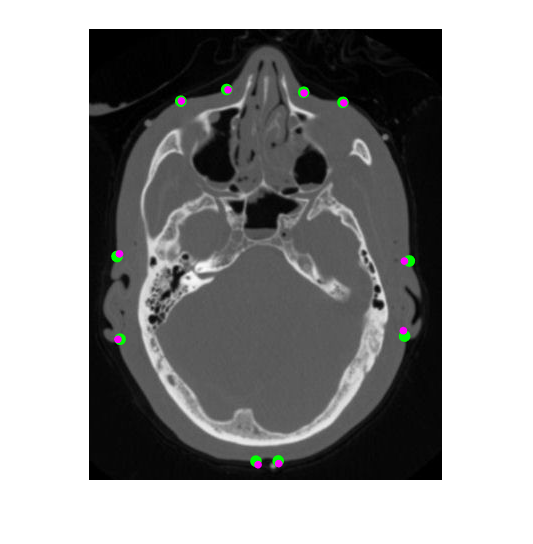

figure();
imshow(dataFrozen);
hold on;
plot(CTFrozenMean(:, 1), CTFrozenMean(:, 2), 'g.', "MarkerSize", 30);
plot(MRITransform(:, 1), MRITransform(:, 2), 'm.', "MarkerSize", 20);
hold off;